# Surface reflectance properties

**The book section:  **#sec-lightfield-properties

Calculate linear model basis functions for surface reflectances.  We use the Parkinnen Munsell data set, as well as several samples from Mike Vrhel.  Perhaps we can find the USGS data set for materials?

Then calculate the product of some daylights and surfaces to illustrate the variation in the incident light field with changes in ambient illumination.

The ieCookTorrance method should illustrate standard models for the BRDFs.

imgdir = '~/Documents/FISE-git/chapters/images/lightfields';
wave = 400:1:700;
exportPlots = false;
fise_plotDefaults;

## Typical reflectance functions

These are samples of clothing, but many other types of objects have smooth spectral reflectance functions, too.

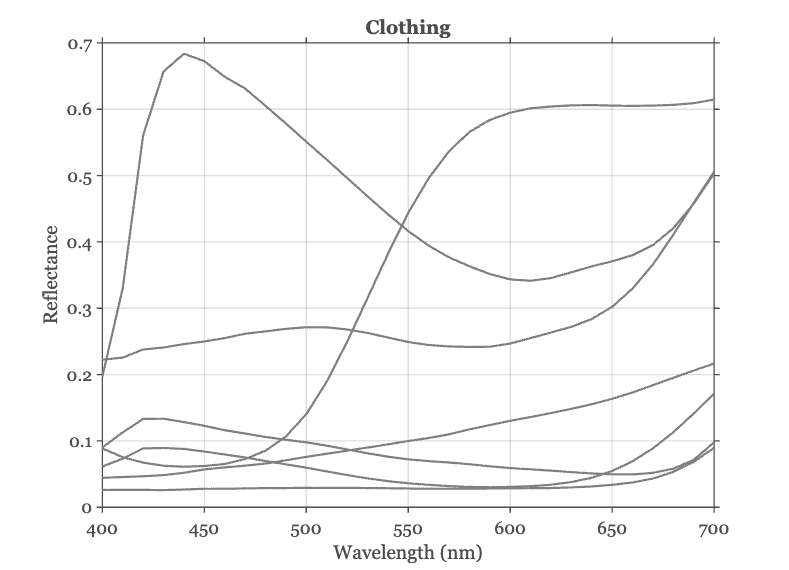

[clothes,~,comment] = ieReadSpectra('Clothes_Vhrel',wave);
plotReflectance(wave,clothes(:,1:6:end),...
    'Color',[0.5 0.5 0.5], ...
    'title','Clothing');
set(gca,'TickDir','out');
if exportPlots
    exportgraphics(gca,fullfile(imgdir,'01-reflectance-clothes.png'),...
        'Resolution',150); %#ok<*UNRCH>
end

## Linear model of Munsell swatches (Parkinnen et al. data)

These are the first three basis functions

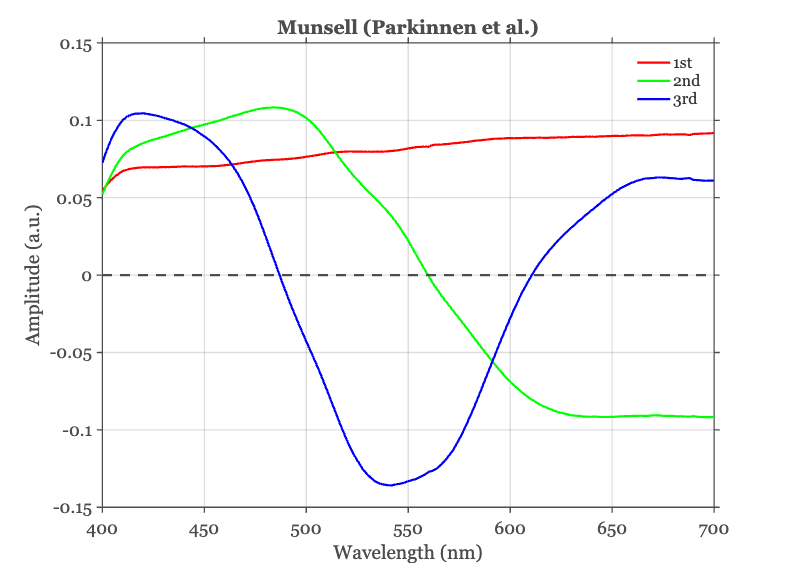

wave = 400:2:700;
munsell = ieReadSpectra('munsell_matte',wave);
[Um,~,~] = svd(munsell,'econ');

ieFigure;
plot(wave,Um(:,1:3)*diag([1,-1,-1]),'LineWidth',2);
grid on;  title('Munsell (Parkinnen et al.)')
xaxisLine;

grid on; xaxisLine; xlabel('Wavelength (nm)'); ylabel('Amplitude (a.u.)')

title('Munsell (Parkinnen et al.)'); 
legend({'1st','2nd','3rd'}); set(gca,'TickDir','out');
if exportPlots
    exportgraphics(gca,fullfile(imgdir,'01-munsell-basis.png'),...
        'Resolution',150);
end

## How well do these fit?

There are 1269 samples in the data set, and here we read in the data at 2 nm sample spacing (151 samples). We can make a scatter plot showing the measured and approximated reflectance of all 191619 values this way.

% Linear model weights for first 3 dimensions
nDim = 5;
wgts = Um(:,1:nDim)'*munsell;

% The approximation
approximation = Um(:,1:nDim)*wgts;

% About 1 percent for 5 dim and 2.5 percent for 3 dim
d = rmse(approximation(:),munsell(:));
fprintf('RMSE %.3f for %d dimensions\n',d,nDim);

RMSE 0.011 for 5 dimensions


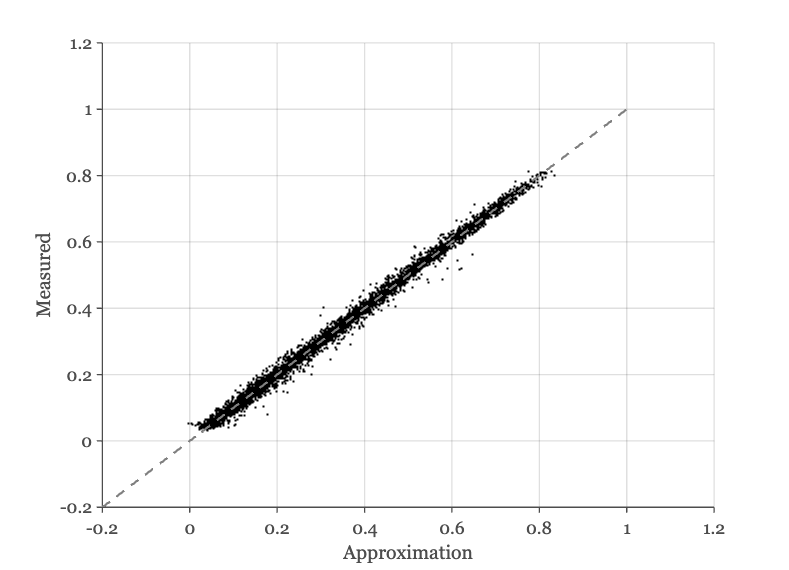


% Show a subsample
nsamples = randi(numel(munsell),[1,10000]);

ieFigure;
scatter(approximation(nsamples),munsell(nsamples),'k.');
grid on;
identityLine;
set(gca,'TickDir','out');
xlabel('Approximation'); ylabel('Measured');
if exportPlots
    exportgraphics(gca,fullfile(imgdir,'01-munsell-scatter.png'),...
        'Resolution',150);
end

## Linear models of various samples

Here are the linear models from different groups of surfaces collected by Mike Vrhel and colleagues. The groups of materials are very different, but the first three basis functions of the linear models are quite similar.

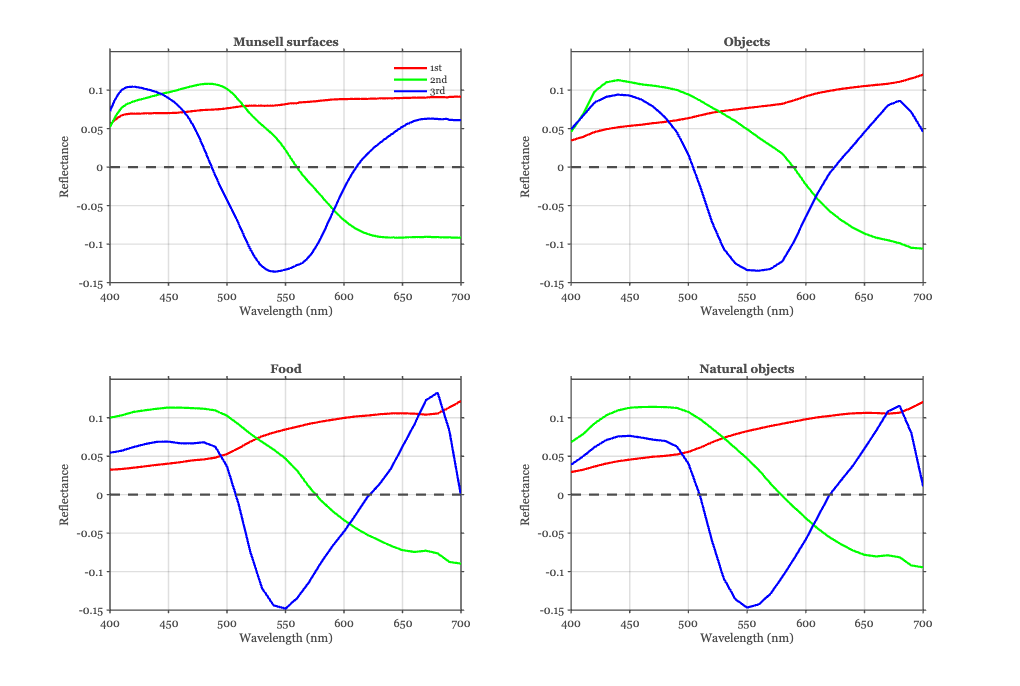

% Should we have a normalized wave option for this method?
nature  = ieReadSpectra('Nature_Vhrel',wave);
objects = ieReadSpectra('Objects_Vhrel',wave);
food    = ieReadSpectra('Food_Vhrel',wave);

[Un, Sn, ~] = svd(nature,'econ');
[Uo, So, ~] = svd(objects,'econ');
[Uf, Sf, ~] = svd(food,'econ');

hdl = ieFigure;
ylim = [-0.15,0.15]; xlim = [400 700];

tiledlayout(2,2);
nexttile;
plotReflectance(wave,Um(:,1:3)*diag([1,-1,-1]),'hdl',hdl, 'title','Munsell surfaces'); hold on;
xaxisLine; set(gca,'ylim',ylim,'xlim',xlim); set(gca,'TickDir','out');
legend({'1st','2nd','3rd'});

nexttile;
plotReflectance(wave,Uo(:,1:3)*diag([-1,-1,-1]),'hdl',hdl, 'title','Objects'); hold on;
xaxisLine; set(gca,'ylim',ylim,'xlim',xlim); set(gca,'TickDir','out');

nexttile;
plotReflectance(wave,Uf(:,1:3)*diag([-1,-1,1]),'hdl',hdl, 'title','Food'); hold on;
xaxisLine; set(gca,'ylim',ylim,'xlim',xlim); set(gca,'TickDir','out');

nexttile
plotReflectance(wave,Un(:,1:3)*diag([-1,1,1]),'hdl',hdl,'title','Natural objects'); hold on;
xaxisLine; set(gca,'ylim',ylim,'xlim',xlim);set(gca,'TickDir','out');

if exportPlots
    set(gcf,'Units','pixels');
    set(gcf,'Position',[131   661   956   643]);
    exportgraphics(gcf,fullfile(imgdir,'01-reflectance-bases.png'),...
        'Resolution',150); set(gcf,'Units','normalized');
    set(gcf,'Units','normalized');
end

### Numerical comparison

We can ask whether the surface reflectances in these different categories span the same subspace by calculating whether the basis functions are within a linear transformation.  For example, can we find a 3x3 transformation that maps the Munsell basis vectors into the Object basis vectors?


$$U_o =U_m \;T$$


The graphs below show that they are rather similar to one another, as measured by where the zero-crossings are for the different basis functions.

Transformation from Munsell (Um) to Nature (Un).

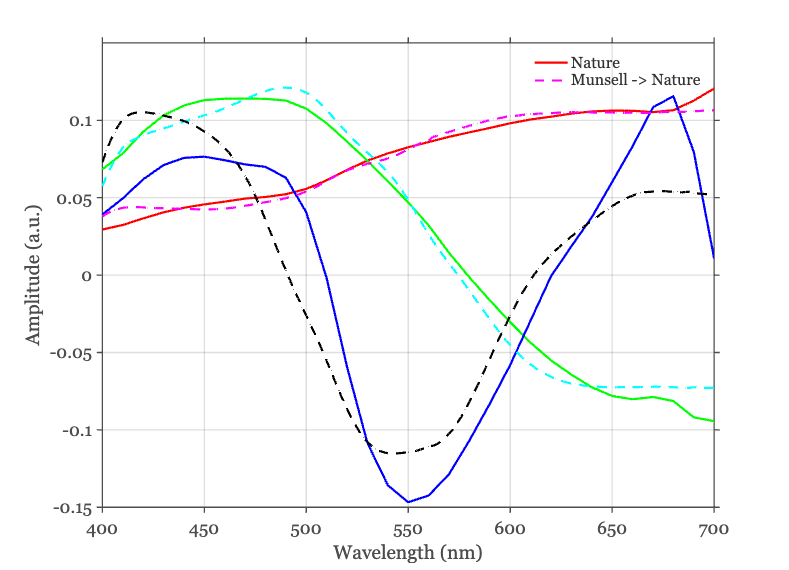

T = pinv(Um(:,1:3))*Un(:,1:3);
UnEst = Um(:,1:3)*T;

ieFigure;
hA = plot(wave,Un(:,1:3)*diag([-1 1 1]),'-','LineWidth',2); hold on;
hB = plot(wave,UnEst*diag([-1 1 1]),'--','LineWidth',2); hold on;
set(gca,'ylim',ylim,'xlim',xlim);
xlabel('Wavelength (nm)');
ylabel('Amplitude (a.u.)');
grid on;set(gca,'TickDir','out');
legend([hA(1) hB(1)],{'Nature','Munsell -> Nature'});

Estimated Food bases from Munsell bases

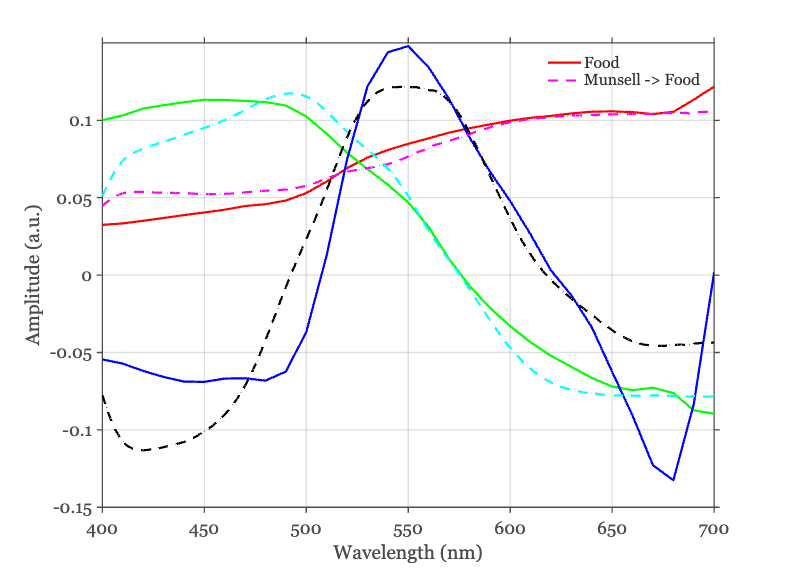


T = pinv(Um(:,1:3))*Uo(:,1:3);
UfEst = Um(:,1:3)*T;

ieFigure;
hA = plot(wave,Uf(:,1:3)*diag([-1 -1 -1]),'-','LineWidth',2); hold on;
hB = plot(wave,UfEst*diag([-1 -1 1]),'--','LineWidth',2); hold on;
set(gca,'ylim',ylim,'xlim',xlim);
xlabel('Wavelength (nm)');
ylabel('Amplitude (a.u.)');
grid on;set(gca,'TickDir','out');
legend([hA(1) hB(1)],{'Food','Munsell -> Food'});